# **3D Solid Cantilever Beam (Brick element)**

This live script is written as a guided walkthrough for a verification benchmark. It compares a known structural response with the result produced by the OpenSeesMatlab workflow. Read the text cells first, then run each code cell in order so that the variables, model state, and recorded results are available for the later sections.

This example presents a three-dimensional cantilever beam modeled using solid (continuum) elements. The objective is to verify the accuracy of displacement and stress predictions obtained from OpenSeesMatlab by comparing them with classical beam theory solutions.

A rectangular beam of length \( L \), width \( b \), and height \( h \) is fixed at one end and subjected to a vertical load at the free end. The beam is modeled using 3D solid elements, and both displacement and stress responses are evaluated.

clear; clc;

opsMAT = OpenSeesMatlab();


  OpenSeesMatlab v3.8.0.2
  OpenSees MEX Interface for MATLAB
  Copyright (c) 2026, By Yexiang Yan

  Type 'help OpenSeesMatlab' in MATLAB for documentation.
  Documentation also available at 
  https://openseesmatlab.readthedocs.io/en/latest/ 



ops = opsMAT.opensees;

ops.wipe();
ops.model('basic', '-ndm', 3, '-ndf', 3);

%% Parameters
L  = 3.0;
b  = 0.2;
h  = 0.3;
E  = 30e9;
nu = 0.25;
P  = 1.0e4;   % 10 kN

nx = 50;
ny = 6;
nz = 6;

dx = L / nx;
dy = b / ny;
dz = h / nz;

%% Material
matTag = 1;
ops.nDMaterial('ElasticIsotropic', matTag, E, nu);

%% Node generation
nodeTag = 0;
nodeId = zeros(nx+1, ny+1, nz+1);

for i = 0:nx
    x = i * dx;
    for j = 0:ny
        y = -b/2 + j * dy;
        for k = 0:nz
            z = -h/2 + k * dz;
            nodeTag = nodeTag + 1;
            nodeId(i+1,j+1,k+1) = nodeTag;
            ops.node(nodeTag, x, y, z);
        end
    end
end

%% Element generation
eleTag = 0;
for i = 1:nx
    for j = 1:ny
        for k = 1:nz
            n1 = nodeId(i  ,j  ,k  );
            n2 = nodeId(i+1,j  ,k  );
            n3 = nodeId(i+1,j+1,k  );
            n4 = nodeId(i  ,j+1,k  );
            n5 = nodeId(i  ,j  ,k+1);
            n6 = nodeId(i+1,j  ,k+1);
            n7 = nodeId(i+1,j+1,k+1);
            n8 = nodeId(i  ,j+1,k+1);

            eleTag = eleTag + 1;
            ops.element('stdBrick', eleTag, ...
                n1,n2,n3,n4,n5,n6,n7,n8, ...
                matTag, 0.0, 0.0, 0.0);
        end
    end
end

%% Boundary conditions at x = 0
for j = 1:(ny+1)
    for k = 1:(nz+1)
        nd = nodeId(1,j,k);
        ops.fix(nd, 1, 1, 1);
    end
end

%% Load at free end x = L
tipFaceNodes = [];
for j = 1:(ny+1)
    for k = 1:(nz+1)
        tipFaceNodes(end+1) = nodeId(nx+1,j,k);
    end
end

fz = -P / numel(tipFaceNodes);

ops.timeSeries('Linear', 1);
ops.pattern('Plain', 1, 1);

for ii = 1:numel(tipFaceNodes)
    ops.load(tipFaceNodes(ii), 0.0, 0.0, fz);
end

opts = opsMAT.vis.defaultPlotModelOptions;
opts.nodes.showLabels = false;
opts.elements.showLabels = false;
opts.loads.showNodal = true;
opsMAT.vis.plotModel(opts=opts);

[OpenSeesMatlab] Model summary
  Nodes: 2499
  Solid elements: 1800


grid off

opsMAT.vis.polyscope.plotModel();

[OpenSeesMatlab] Backend: openGL3_glfw -- Loaded openGL version: 3.3.0 NVIDIA 610.74


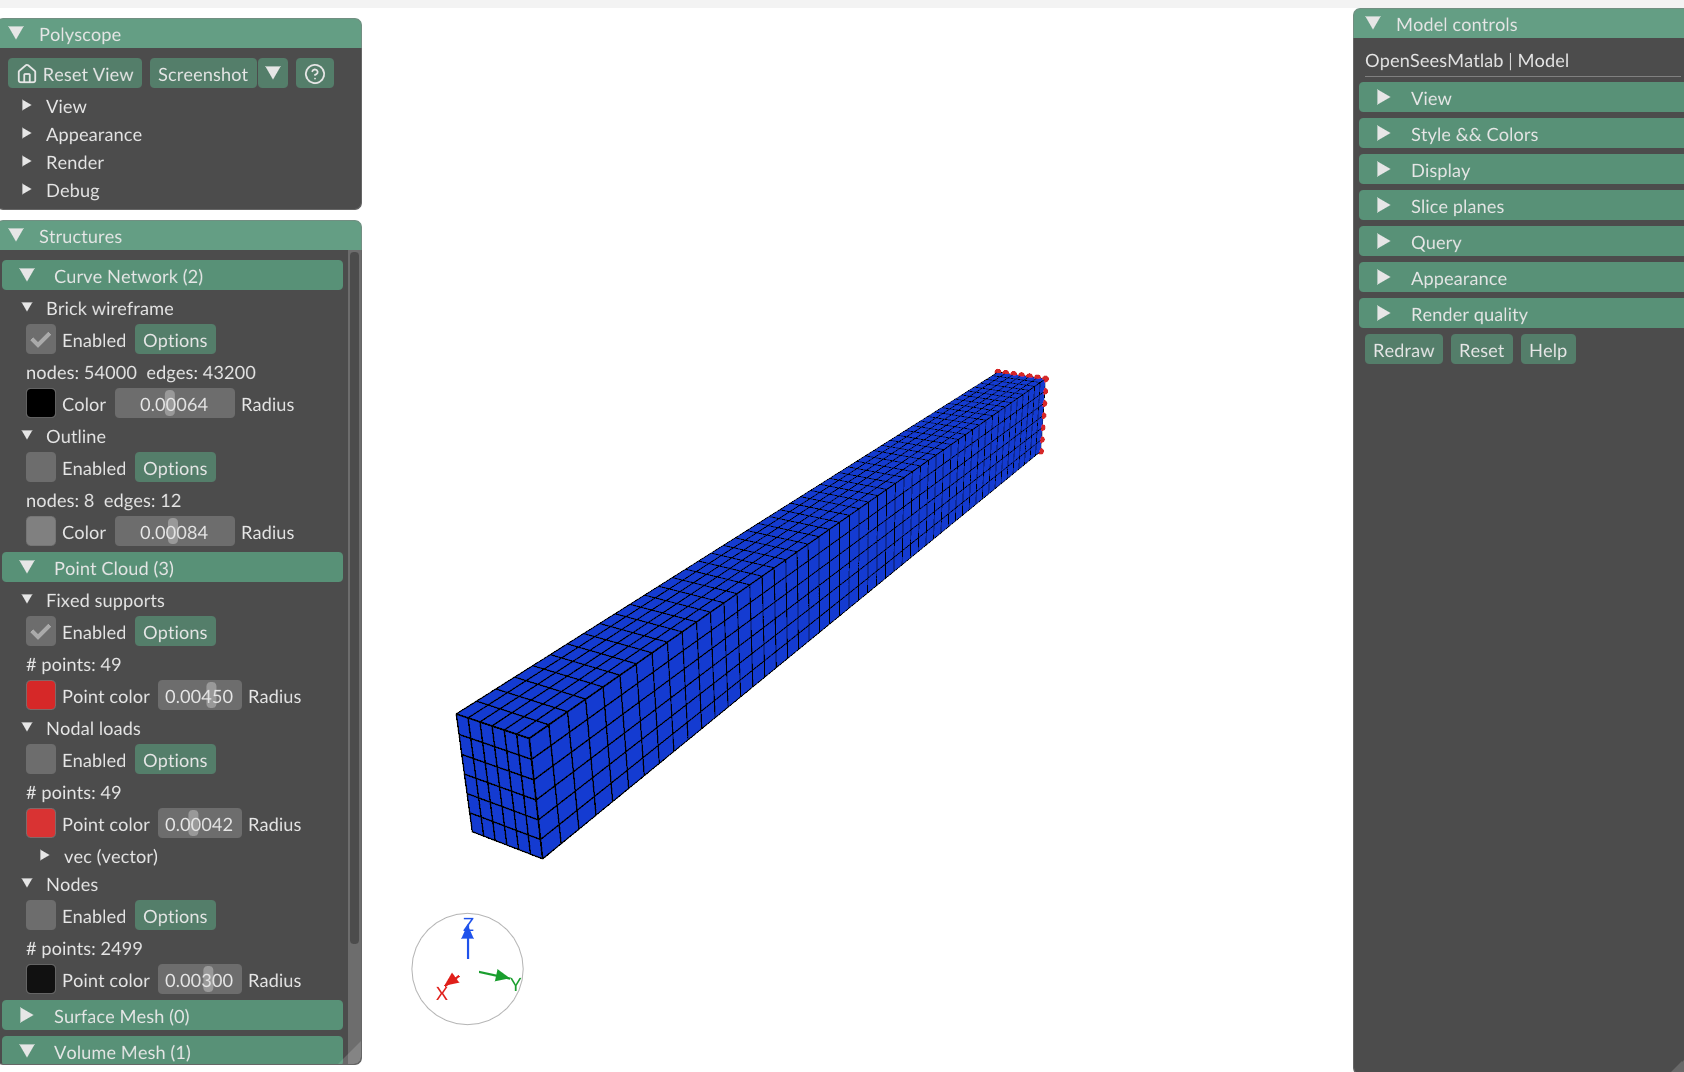

Nsteps = 2;
ops.constraints('Plain');
ops.numberer('RCM');
ops.system('BandGeneral');
ops.test('NormDispIncr', 1e-10, 50);
ops.algorithm('Newton');
ops.integrator('LoadControl', 1.0/Nsteps);
ops.analysis('Static');

ODB = opsMAT.post.createODB("myODB", projectGaussToNodes="extrapolate");  % create ODB

Output file: .openseesmatlab.output\Responses-myODB.odb\output.h5


ok = ops.analyze(Nsteps);
ODB.close();

nodeResp = opsMAT.post.getNodalResponse("myODB");

opts = opsMAT.vis.defaultPlotNodalResponseOptions;
opts.fixed.show = false;
opts.surf.showEdges = false;
opts.deform.showUndeformed = true;

opsMAT.vis.plotNodalResponse(nodeResp, respType="disp", stepIdx="absMax", respComponent="UZ", opts=opts);
colormap("jet")
axis off
view([0 0]);

%% Theoretical solution
I = b*h^3/12;
w_theory = P*L^3/(3*E*I);

%% By OpenSeesMatlab
uz = nodeResp.disp.uz;
w_fe = min(uz(:));


fprintf("Maximal deflection in the z-direction:\n" + ...
        "  OpenSeesMatlab:  %g \n" + ...
        "  Theoretical:     %g \n", ...
        w_fe, -w_theory);

Maximal deflection in the z-direction:
  OpenSeesMatlab:  -0.00656224 
  Theoretical:     -0.00666667 


solidResp = opsMAT.post.getElementResponse("myODB", eleType="Solid");

opts = opsMAT.vis.defaultPlotContinuumResponseOptions;
opts.fixed.show = false;
opts.surf.showEdges = false;

opsMAT.vis.plotContinuumResponse(solidResp, ...
    respType="StressAtNode", respComponent="sxx", opts=opts);
axis off
view([0 0]);


sigma_theory = P*L*(h/2)/I;
sxx = solidResp.StressAtNode.sxx;
sxx_fe = max(sxx(:));
fprintf("Maximal sxx stress:\n" + ...
        "  OpenSeesMatlab: %g \n" + ...
        "  Theoretical   : %g \n", ...
        sxx_fe, sigma_theory);

Maximal sxx stress:
  OpenSeesMatlab: 1.13752e+07 
  Theoretical   : 1e+07 


### Visualization by GUI

opsMAT.vis.plotContinuumResponseGUI(solidResp);

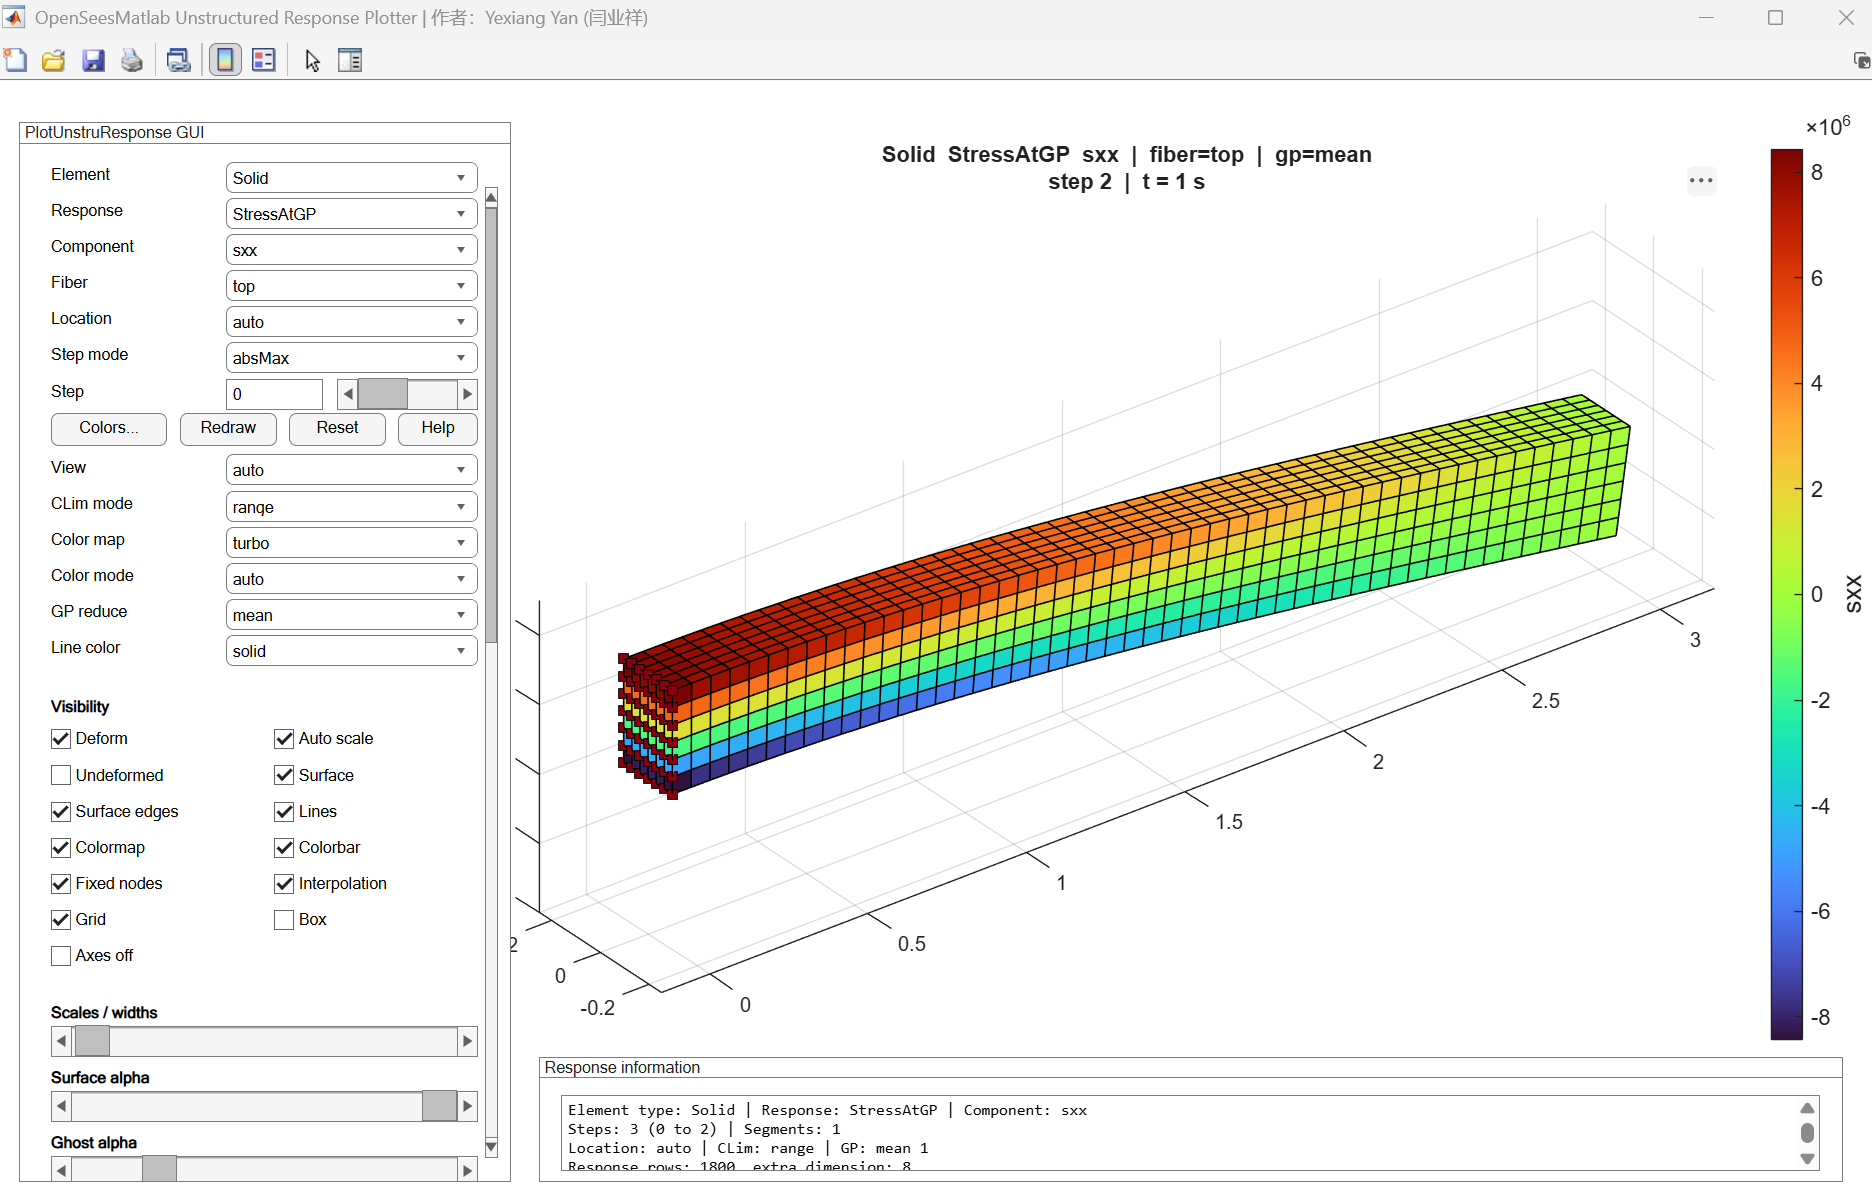

opsMAT.vis.polyscope.plotNodalResponse(nodeResp);

[OpenSeesMatlab] Backend: openGL3_glfw -- Loaded openGL version: 3.3.0 NVIDIA 610.74